#         EEE 321 - Signals and Systems - Lab 6 - IIR Filter

## Tuna Şahin - 22201730


$$\textrm{ID}=22201730$$


$N_1 =7,$ $N_2 =1$, $M_1 =9,M_2 =3,L=12$

##     Pole and Zero Placements:

    We place the poles near the passband and place the zeros along the stopband. We must place the poles inside the unit circle if we want the system to be stable and causal. 

Zeros are uniformly spaced along the stopband to ensure we have a flat stopband.

boundary1 = 150; %20;
zeros1 = [cos(linspace(-pi/boundary1,pi/boundary1,3))+1j*sin(linspace(-pi/boundary1,pi/boundary1,3))];
boundary2 = 1.6; %2; 
zeros2 = [cos(linspace(pi/boundary2,(2*boundary2-1)*pi/boundary2,9))+1j*sin(linspace(pi/boundary2,(2*boundary2-1)*pi/boundary2,9))];

Poles are chosen as conjugate symmetric pairs. 6 along the positive passband and 6 along the negative passband.

boundary_p2 = 2.3; %2.5;
boundary_p1 = 15;
pole_radius = 0.65;
poles1 = [pole_radius*cos(linspace(pi/boundary_p1,pi/boundary_p2,6))+pole_radius*j*sin(linspace(pi/boundary_p1,pi/boundary_p2,6))];
poles1(3:4) = poles1(3:4)*(0.4/0.65)

poles1 =    0.6358 + 0.1351i   0.5879 + 0.2773i   0.3130 + 0.2490i   0.2476 + 0.3142i   0.2746 + 0.5891i   0.1322 + 0.6364i


poles2 = [pole_radius*cos(linspace(pi/boundary_p1,pi/boundary_p2,6))+pole_radius*j*sin(linspace(-pi/boundary_p1,-pi/boundary_p2,6))];
poles2(3:4) = poles2(3:4)*(0.4/0.65)

poles2 =    0.6358 - 0.1351i   0.5879 - 0.2773i   0.3130 - 0.2490i   0.2476 - 0.3142i   0.2746 - 0.5891i   0.1322 - 0.6364i


Afterwards we will plot these zeros and plots.

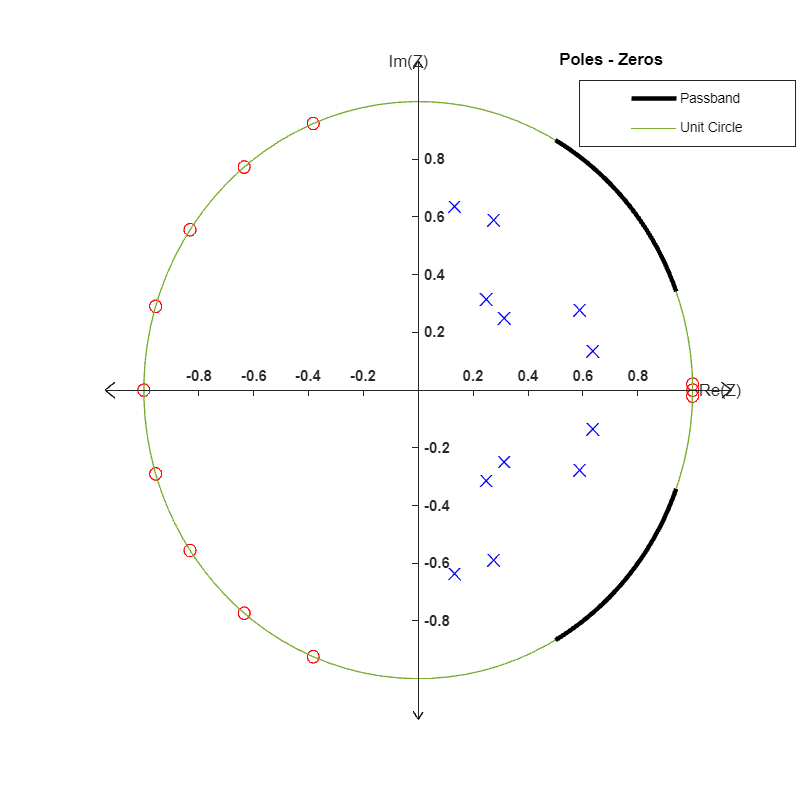

zerosT = [zeros1 zeros2];
polesT = [poles1 poles2];
clf;
polezeroplot(polesT,zerosT,'Poles - Zeros','Z','on',[800 800]) %function to plot poles and zeros
h = gobjects(3, 1);
h(1) = plot(cos(linspace(0,2*pi,100)),sin(linspace(0,2*pi,100)),'color',[0.4660 0.6740 0.1880],'DisplayName', 'Unit Circle'); %unit circle
h(2) = plot(cos(linspace(pi/9,pi/3,100)),sin(linspace(pi/9,pi/3,100)),'black','LineWidth',3,'DisplayName', 'Passband');   %passband positive side
h(3) = plot(cos(linspace(pi/9,pi/3,100)),sin(linspace(-pi/9,-pi/3,100)),'black','LineWidth',3,'DisplayName', 'Passband'); %passband negative side
legend(h([2 1])); %add the legend
hold off
legend("Position", [0.7171 0.8192 0.2675, 0.0812])

Total of 12 poles and 12 roots are included in my design. Equal number of zeros and poles ensures no additional poles or zeros at the origin.

$H\left(z\right)=\frac{Y\left(z\right)}{X\left(z\right)}=\frac{\prod_1^{12} \frac{\left(z-z_i \right)}{z}}{\prod_1^{12} \frac{\left(z-p_i \right)}{z}}$ since $Y\left(z\right)=\prod_1^{12} \frac{\left(z-p_i \right)}{z}=X\left(z\right)\prod_1^{12} \frac{\left(z-z_i \right)}{z}$

nom = [];
for i = zerosT
    if isempty(nom)
        nom = [-i 1];
    else
        nom = conv(nom,[-i 1]); %polynomial multiplication
    end
end
denom = [];
for i = polesT
    if isempty(denom)
        denom = [-i 1];
    else
        denom = conv(denom,[-i 1]); %polynomial multiplication
    end
end
%nom = real(nom); %signal is already real. Get rid of +0j to make sure we dont have a error due to floating point arithmatic in the future
%denom = real(denom); % get rid of +0j to make sure we dont have a error due to floating point arithmatic in the future

##     Analytical Calculations:

disp(array2table([[0:12];real(nom);real(denom)]))

       Var1         Var2         Var3        Var4       Var5      Var6         Var7         Var8       Var9      Var10     Var11      Var12     Var13
    __________    _________    ________    ________    ______    _______    ___________    _______    ______    _______    ______    _______    _____

             0            1           2           3         4          5              6          7         8          9        10         11     12  
            -1      -3.6114     -4.2101      2.0724     11.38     11.864    -3.5527e-15    -11.864    -11.3

Using these values, we can write the transforms as:


$$X\left(z\right)=\left(1+2\ldotp 19z+2\ldotp 5115z^2 +1\ldotp 4052z^3 -0\ldotp 7596z^4 -2\ldotp 8659z^5 -3\ldotp 7344z^6 -2\ldotp 8659z^7 -0\ldotp 7596z^8 +1\ldotp 4052z^9 +2\ldotp 5115z^{10} +2\ldotp 19z^{11} +z^{12} \right)z^{-12}$$



$$Y\left(z\right)=\left(0\ldotp 2824-2\ldotp 8034z+13\ldotp 5897z^2 +-42\ldotp 2332z^3 +93\ldotp 3545z^4 -154\ldotp 2724z^5 +195\ldotp 1977z^6 -190\ldotp 4598z^7 +142\ldotp 2871z^8 -79\ldotp 4692z^9 +31\ldotp 5696z^{10} -8\ldotp 04z^{11} +z^{12} \right)z^{-12}$$



$$H\left(z\right)=\frac{0\ldotp 2824-2\ldotp 8034z+13\ldotp 5897z^2 +-42\ldotp 2332z^3 +93\ldotp 3545z^4 -154\ldotp 2724z^5 +195\ldotp 1977z^6 -190\ldotp 4598z^7 +142\ldotp 2871z^8 -79\ldotp 4692z^9 +31\ldotp 5696z^{10} -8\ldotp 04z^{11} +z^{12} }{1+2\ldotp 19z+2\ldotp 5115z^2 +1\ldotp 4052z^3 -0\ldotp 7596z^4 -2\ldotp 8659z^5 -3\ldotp 7344z^6 -2\ldotp 8659z^7 -0\ldotp 7596z^8 +1\ldotp 4052z^9 +2\ldotp 5115z^{10} +2\ldotp 19z^{11} +z^{12} }$$


All of these polynomials (or division of polynomials for $H\left(z\right)$) can be converted to polynomials of $z^{-1}$. We distribute $z^{-12}$ for $X\left(z\right)\;\textrm{and}\;Y\left(z\right)$. For $H\left(z\right)$ we use a simple engineering procedure of multiplying by 1 which can also be written as:$\left(\frac{z^{-12} }{z^{-12} }\right)$


$$X\left(z\right)=z^{-12} +2\ldotp 19z^{-11} +2\ldotp 5115z^{-10} +1\ldotp 4052z^{-9} -0\ldotp 7596z^{-8} -2\ldotp 8659z^{-7} -3\ldotp 7344z^{-6} -2\ldotp 8659z^{-5} -0\ldotp 7596z^{-4} +1\ldotp 4052z^{-3} +2\ldotp 5115z^{-2} +2\ldotp 19z^{-1} +1$$



$$Y\left(z\right)=0\ldotp 2824z^{-12} -2\ldotp 8034z^{-11} +13\ldotp 5897z^{-10} -42\ldotp 2332z^{-9} +93\ldotp 3545z^{-8} -154\ldotp 2724z^{-7} +195\ldotp 1977z^{-6} -190\ldotp 4598z^{-5} +142\ldotp 2871z^{-4} -79\ldotp 4692z^{-3} +31\ldotp 5696z^{-2} -8\ldotp 04z^{-1} +1$$



$$H\left(z\right)=\frac{0\ldotp 2824z^{-12} -2\ldotp 8034z^{-11} +13\ldotp 5897z^{-10} -42\ldotp 2332z^{-9} +93\ldotp 3545z^{-8} -154\ldotp 2724z^{-7} +195\ldotp 1977z^{-6} -190\ldotp 4598z^{-5} +142\ldotp 2871z^{-4} -79\ldotp 4692z^{-3} +31\ldotp 5696z^{-2} -8\ldotp 04z^{-1} +1}{z^{-12} +2\ldotp 19z^{-11} +2\ldotp 5115z^{-10} +1\ldotp 4052z^{-9} -0\ldotp 7596z^{-8} -2\ldotp 8659z^{-7} -3\ldotp 7344z^{-6} -2\ldotp 8659z^{-5} -0\ldotp 7596z^{-4} +1\ldotp 4052z^{-3} +2\ldotp 5115z^{-2} +2\ldotp 19z^{-1} +1}$$


The second expression of $H\left(z\right)$ allows us to express $y\left\lbrack n\right\rbrack$ as:

$y\left\lbrack n\right\rbrack =-\sum_{k=1}^{12} a_k y\left\lbrack n-k\right\rbrack +\sum_{l=0}^{12} b_l x\left\lbrack n-l\right\rbrack$ where ${a_k }^{\prime } s\;\textrm{and}\;{b_l }^{\prime } s$ are given in the table above. 

##     Question 1:

The pole zero plot was already given above in the placement phase. Using the coefficients of $Y\left(z\right),X\left(z\right)$ which are equivalent to the ${a_k }^{\prime } s$ and ${b_l }^{\prime } s$. We can write the recursive algorithm necessary to calculate $y\left\lbrack n\right\rbrack$ as the following:

y = [0 0 0 0 0 0 0 0 0 0 0 0];
x = [0 0 0 0 0 0 0 0 0 0 0 0 1];

for i = 1:100 %Recursive Algorithm to Calculate y[n]
    yn = -1*sum(y(end-11:end).*denom(1:end-1))+sum(x(end-12:end).*nom); %multiply coefficients with their respective values and add them 
    x = [x 0]; %increase the size of x for compatilibility
    y = [y yn]; %append yn to the end of y
end

Arrange the values into a table for easier readibilitiy. Take the real part of the variables so they don't unnecessarily print $+0j$. We already know the coefficients imaginary part must be 0.

table=array2table([real(y(1:10));real(y(11:20));real(y(21:30));real(y(31:40));real(y(41:50));real(y(51:60));real(y(61:70));real(y(71:80));real(y(81:90));real(y(91:100));real(y(101:110))]);
disp(table)

       Var1           Var2           Var3           Var4           Var5           Var6           Var7           Var8           Var9           Var10   
    ___________    ___________    ___________    ___________    ___________    ___________    ___________    ___________    ___________    ___________

              0              0              0              0              0              0              0              0              0              0
              0              0              1         7.9937         29.633         64.889          84.71         42.257         -74.69        -201.65
         -235.1        -131.06         43.413          

We need to calculate the Fourier Transform of the function. Luckily, we already have the z transform. We can substitute $e^{j\omega \;}$instead of $z$ to obtain the Fourier Transform.

omega = linspace(0,2*pi,10000);
nomsum = zeros(1,length(omega));
denomsum = zeros(1,length(omega));
finalsum = zeros(1,length(omega));
for i = 0:12
    nomsum = nomsum + (nom(i+1)*(exp(j*omega).^(i-12)));
end
for i = 0:12
    denomsum = denomsum + (denom(i+1)*(exp(j*omega).^(i-12)));
end
finalsum = nomsum./denomsum; %elementwise divide for each

Plot the impulse response:

clf;
subplot(1,3,1)
finestem([-11:length(y)-12],real(y),'Impulse Response','h[n]','n',[-15 55],[-300 300],'off',[1200 400])

Plot the magnitutes of the fourier transform:

subplot(1,3,2)
fineplot(omega,abs(finalsum)/100,'|H(e^{j\omega})|','\omega','H(e^{j\omega})\times10^2',[0 2*pi],[0 20],'off',[1200 400])
set(gca,'XTick',[0 pi/9 pi/3 pi 5*pi/3 17*pi/9],'XTickLabel',{0,'','\pi/3','\pi/2','5\pi/3',''})

Plot the phase of the fourier transform:

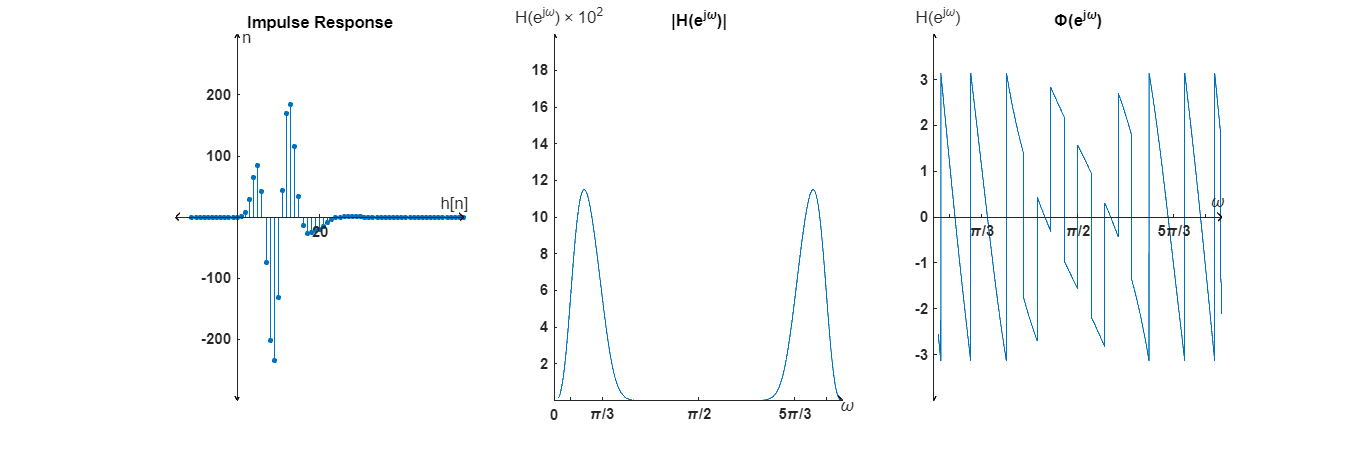

subplot(1,3,3)
fineplot(omega,angle(finalsum),'\Phi(e^{j\omega})','\omega','H(e^{j\omega})',[0 2*pi],[-4 4],'off',[1200 400])
set(gca,'XTick',[0 pi/9 pi/3 pi 5*pi/3 17*pi/9],'XTickLabel',{0,'','\pi/3','\pi/2','5\pi/3',''})

##     Question 2:

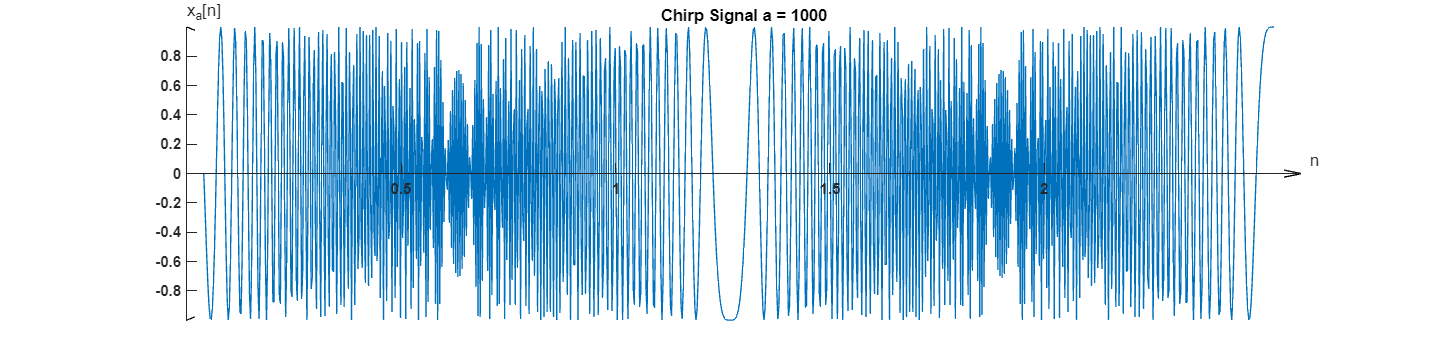

a = 1000; 
b = sqrt(pi/(a*512))*1024;
xa = cos(linspace(0,b,1024).^2*a);
filewrite(xa,'q2xa');
n = linspace(0,b,1024);
clf;
fineplot(n,xa,'Chirp Signal a = 1000','n','x_a[n]',[0 2.6],[-1 1],'off',[1600 400])

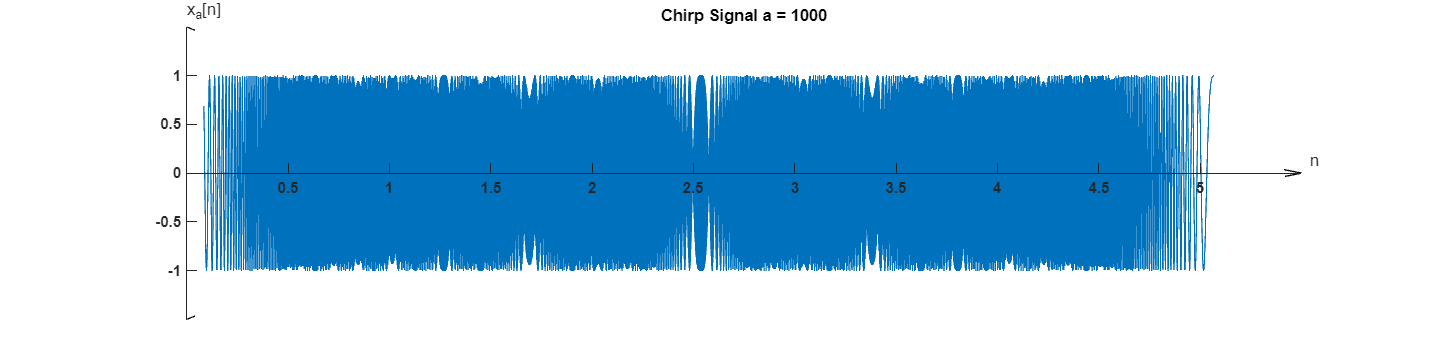

a = 1000; %given in Q3
a_length = 8192;
b = sqrt(pi/(a*8192))*(a_length-1);
n = linspace(0,b,a_length);
xa2 = cos(n.^2*a);
filewrite(xa2,'q3xa');
clf;
fineplot(n,xa2,'Chirp Signal a = 1000','n','x_a[n]',[0 5.5],[-1.5 1.5],'off',[1600 400])

##     Question 3:

Implementing the same algorithm that was used for the impulse response with a slight change to acoomodate for larger inputs can be with the following code:

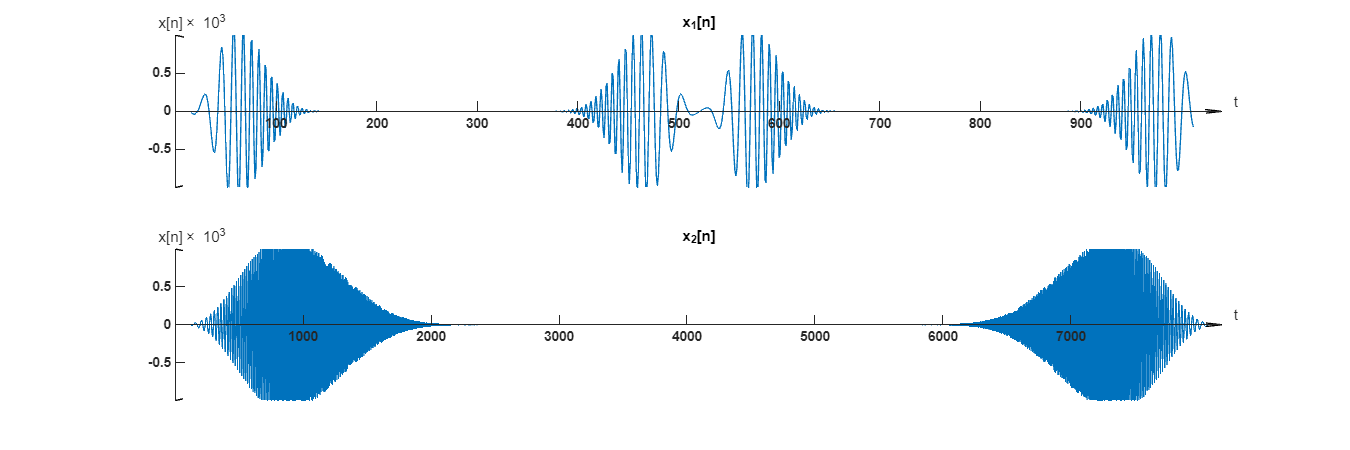

clf;
subplot(2,1,1)
y3 = [0 0 0 0 0 0 0 0 0 0 0 0];
x3 = xa;
for i = 1:1000 
    yn3 = -1*sum(y3(end-11:end).*denom(1:end-1))+sum(x3(i+1:i+13).*nom);
    y3 = [y3 yn3];
end
filewrite(y3,'q3y1')
fineplot(1:length(y3),real(y3)/1000,'x_1[n]','t','x[n]\times 10^{3}',[0 1040], [-1 1],'off',[1200 400])
subplot(2,1,2)
y4 = [0 0 0 0 0 0 0 0 0 0 0 0];
x4 = xa2;
for i = 1:8170
    yn4 = -1*sum(y4(end-11:end).*denom(1:end-1))+sum(x4(i+1:i+13).*nom);
    y4 = [y4 yn4];
end
filewrite(y4,'q3y2')
fineplot(1:length(y4),real(y4)/1000,'x_2[n]','t','x[n]\times 10^{3}',[0 length(y4)], [-1 1],'off',[1200 400])

This test, passing a chirp signal through the system, can provide us with information about the system's frequency response. Since the chirp signal has diffferent frequencies at different intervals, the system only passes the intervals that correspond to the passband of the filter.

##     Question 4:

% yar = fileread('q3xa');
% sound = audioplayer(yar/max(yar),sqrt(pi/8192000)^-1); %invert Ts to get Fs
% while 1 
%     playblocking(sound) 
% end

The original analog signal and the interpolated versions are nothing alike. This is because the original chirp signal has a frequency that increases indefinately meanwhile the interpolated signal's fundamental frequency is limited by the Nyquist frequency. After a certain frequency, the interpolated version will experience aliasing and the frequency will start decreasing again. 

The moment the frequency drops back to 0 marks one period of the signal. However, the original chirp signal was not periodic.

##     Question 5:

% yar = fileread('q3y2');
% sound = audioplayer(yar/max(yar),sqrt(pi/8192000)^-1);
% while 1 
%     playblocking(sound) 
% end

We can observe that the filter is so selective, there is no sound outside the passband. The signal is inside the passband for only a tiny interval so it sounds like two short pulses of low frequency sound. There are two pulses since the signal's frequency increases and decreases passing each frequency twice.

##     Question 6:

We can realise that our passband of $\left\lbrack \frac{\pi }{9},\frac{\pi }{3}\right\rbrack$ is equivalent to [563rad/s, 1691rad/s] for the signal $y_2 \left\lbrack n\right\rbrack$.

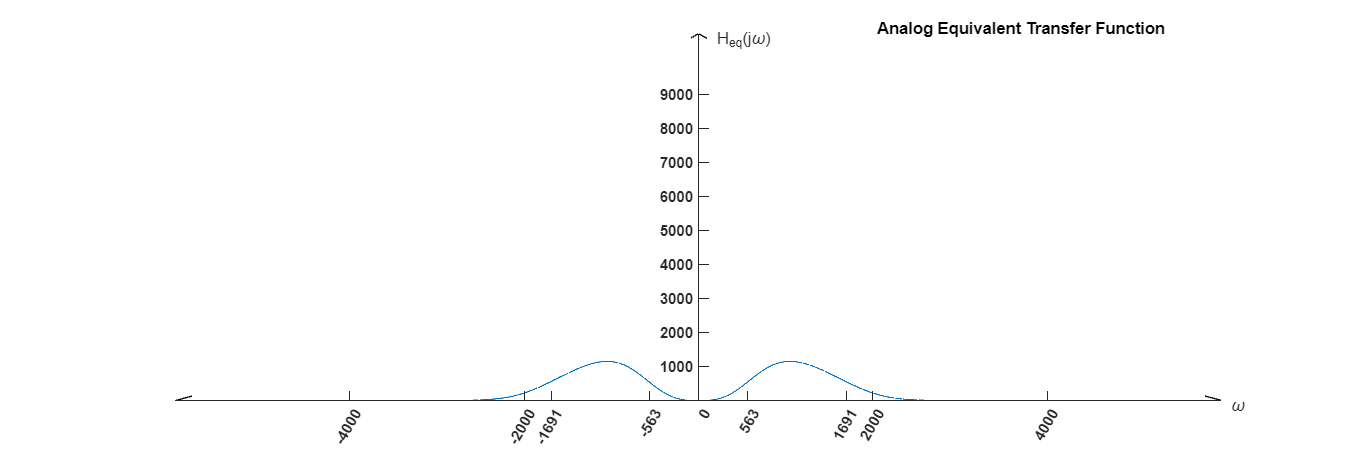

omega2 = linspace(-pi,pi,10000);
nomsum2 = zeros(1,length(omega2));
denomsum2 = zeros(1,length(omega2));
finalsum2 = zeros(1,length(omega2));
for i = 0:12
    nomsum2 = nomsum2 + (nom(i+1)*(exp(j*omega2).^(i-12)));
end
for i = 0:12
    denomsum2 = denomsum2 + (denom(i+1)*(exp(j*omega2).^(i-12)));
end
finalsum2 = nomsum2./denomsum2; %elementwise divide for each
clf;
fineplot(omega2*sqrt(8192000/pi),abs(finalsum2),'Analog Equivalent Transfer Function','\omega','H_{eq}(j\omega)',[-6000 6000],[0 10800],'off',[1200 400])
set(gca,'XTick',[-4000 -2000 -1691 -563 0 563 1691 2000 4000],'XTickLabel',{-4000,-2000,-1691,-563,0,563,1691,2000,4000},'XTickLabelRotation',60)

k2 = find(abs(finalsum2) == max(abs(finalsum2)));
disp(abs(finalsum2(k2)))

   1.1504e+03



k = find(floor(omega2*sqrt(8192000/pi))==563);
disp(abs(finalsum2(k)))

  543.9067



k3 = find(floor(omega2*sqrt(8192000/pi))==1691);
disp(abs(finalsum2(k3)))

  557.6385



##     Question 7:

% [xn,Fs] = audioread('yelkenler_bicilecek.mp3',[1 inf],'double');
% xn = xn(3250000:3750000,1).';
% %yn = conv(xn,real(y)); %fast method but not exact
% x3 = [[0 0 0 0 0 0 0 0 0 0 0 0] xn];
% y3 = [0 0 0 0 0 0 0 0 0 0 0 0];
% temp = 0;
% for i = 1:(length(x3))
%     if temp ~= floor(100*i/(length(x3))) %shows the percentage of completion
%         disp(temp)
%     end
%     temp = floor(100*i/(length(x3)-100));
%     yn3 = -1*sum(y3(end-11:end).*denom(1:end-1))+sum(x3(i+1:i+13).*nom);
%     y3 = [y3 yn3];
%     x3 = [x3 0];
% end
% audiowrite('my_filtered_song.mp3',real(y3),Fs)
% y3 = y3*0.5/max(y3);
% %clf;
% %plot(1:length(yn),yn)
% sound3 = audioplayer(xn,Fs);
% %playblocking(sound3)
% sound4 = audioplayer(y3,Fs);
% playblocking(sound4)

##     Question 8:

% [xn,Fs] = audioread('my_recording.mp3',[1 inf],'double');
% disp(Fs)
% x4 = [[0 0 0 0 0 0 0 0 0 0 0 0] xn.'];
% y4 = [0 0 0 0 0 0 0 0 0 0 0 0];
% temp = 0;
% for i = 1:(length(x4))
%     % if temp ~= floor(100*i/(length(x4))) %shows the percentage of
%     % completion
%     %     disp(temp)
%     % end
%     % temp = floor(100*i/(length(x4)-100));
%     yn4 = -1*sum(y4(end-11:end).*denom(1:end-1))+sum(x4(i+1:i+13).*nom);
%     y4 = [y4 yn4];
%     x4 = [x4 0];
% end
% y4 = y4*0.5/max(y4);
% sound3 = audioplayer(x4,Fs);
% playblocking(sound3)
% audiowrite('my_filtered_recording.mp3',abs(y4),Fs)
% sound4 = audioplayer(y4,Fs);
% playblocking(sound4)

% temp_conv_filtered = real(conv(x4,y));
% audiowrite('conv_filtered_recording.mp3',temp_conv_filtered*0.5/max(temp_conv_filtered),Fs) 

# Functions

##     polezeroplot Function:

Provides a plot with the standart style of pole and zero plotting.

function polezeroplot(poles,zeros,titlename,variableName,holdstate,size)
    maxx = max(real([zeros poles]));
    minx = min(min(real(zeros),min(real(poles))));
    maxy = max(max(imag(zeros),max(imag(poles))));
    miny = min(min(imag(zeros),min(imag(poles))));
    Dx = maxx-minx;
    Dy = maxy-miny;
    dx = Dx/105;
    dy = Dy/85;
    dx = max(dx,dy);
    dy = max(dx,dy);
    hold on
    for i = poles
        plot([(real(i)-dx) (real(i)+dx)],[(imag(i)-dy) (imag(i)+dy)],'blue')
        plot([(real(i)+dx) (real(i)-dx)],[(imag(i)-dy) (imag(i)+dy)],'blue')
    end
    for i = zeros
        t = linspace(0,2*pi,20);
        zx = cos(t)*dx + real(i);
        zy = sin(t)*dy + imag(i);
        plot(zx,zy,'red')
    end
    xlimits = [min((miny-10*dy),(minx-3*dx)) max((maxx+3*dx),(maxy+10*dy))];
    ylimits = [min((miny-10*dy),(minx-3*dx)) max((maxx+3*dx),(maxy+10*dy))];
    fineplot((0),(0),titlename,strcat('Re(',variableName,')'),strcat('Im(',variableName,')'),xlimits,ylimits,holdstate,size)
end

##     fileread & filewrite Function:

Saves a given array to a txt file with the specified name. Returns the same array after reading it from the same txt file.

function filewrite(x,name)
    filename = append(name,'.txt');
    % open your file for writing
    file1 = fopen(filename,'wt');
    % write the matrix
    fprintf(file1,'%f\n',x');
    % close the file
    fclose(file1);
end

function xread = fileread(name)
    filename = append(name,'.txt');
    % open your file for reading
    file1 = fopen(filename,'r');
    % write the matrix
    xread = fscanf(file1,'%f\n');
    % close the file
    fclose(file1);
end 

##     Unit Step Function:

function un = u(n)
    if n < 0
        un = 0;
    else
        un = 1;
    end
end

##     fineplot and finestem Functions:

The stem and plot functions with other configurations to get the same style as the book:

- titlename,xaxisname,yaxisname all take string values that determine the corresponding text.

- xlimits,ylimits take 1x2 arrays that hold the limits of the plot in arbitrary order

- holdstate should take holdstate = 'off' as an input if you don't want to plot to be held any other input will not hold the plot

function fineplot(n,x,titlename,xaxisname,yaxisname,xlimits,ylimits,holdstate,size)
    %even if the limits are reverse this section corrects the order
    if ylimits(1) > ylimits(2)
        ylimits = [ylimits(2) ylimits(1)];
    end
    if xlimits(1) > xlimits(2)
        xlimits = [xlimits(2) xlimits(1)];
    end
    
    %these measures are necessary for positioning arrows, labels etc. 
    dx = ((xlimits(2)-xlimits(1))/65);
    dy = ((ylimits(2)-ylimits(1))/85);

    %this section is to not plot values that overlap with the arrows
    lowindex = 1;
    highindex = length(n);
    for i = n   
        if (i > xlimits(1) + dx) && (lowindex == 1)
            lowindex = find(n==i);
        end
        if (i > xlimits(2) - dx) && (highindex == 1)
            highindex = find(n==i)-1;
        end
    end
    if n(lowindex) > 0 %we allow points to be drawn at the origin
        lowindex = lowindex - 1;
    end
    
    if n(highindex) < 0 %we allow points to be drawn at the origin
        highindex = highindex + 1;
    end

    
    n = n(lowindex:highindex);
    x = x(lowindex:highindex);

    %this section is responsible for axis configuration
    plot(n,x)
    xlim(xlimits)
    ylim(ylimits)
    set(get(gca,'XLabel'),'Visible','on')
    set(gca,'XAxisLocation','origin', 'box','off')
    set(gca,'YAxisLocation','origin')
    set(get(gca, 'XAxis'), 'FontWeight', 'bold')
    set(get(gca, 'YAxis'), 'FontWeight', 'bold');
    set(get(gca,'YLabel'),'Visible','on')
    set(gca,'Layer','top')
    set(gcf,'position',[(xlimits(2)-xlimits(1))/2 , (ylimits(2)-ylimits(1))/2 , size(1) , size(2)])
    
    %deletes the ticks that overlap with arrows
    xticks('auto');
    xt = xticks;
    xticks(xt(2:length(xt)-1));
    yticks('auto');
    yt = yticks;
    yticks(yt(2:length(yt)-1));
    
    % determining the ylevel to draw the arrows on the x axis
    if ((ylimits(1) * ylimits(2)) < 0) 
        xal = 0;
    elseif ylimits(1) < 0
        xal = ylimits(2);
    else
        xal = ylimits(1);
    end

    %plotting the arrows
    hold on
    if xlimits(2) > 0
        plot([(xlimits(2)-dx) xlimits(2) (xlimits(2)-dx)],[xal+dy xal xal-dy],'k') %xaxis right arrow 
    end
    if xlimits(1) < 0
        plot([xlimits(1)+dx xlimits(1) xlimits(1)+dx],[xal+dy xal xal-dy],'k') %xaxis left arrow 
    end 
    plot([0 0],[ylimits(2) ylimits(1)],'k')% y axis
    if ylimits(2) > 0 
        plot([-dx/2 0 dx/2],[ylimits(2)-dy ylimits(2) ylimits(2)-dy],'k') %yaxis top arrow 
    end
    if ylimits(1) < 0
        plot([-dx/2 0 dx/2],[ylimits(1)+dy ylimits(1) ylimits(1)+dy],'k') %yaxis bottom arrow 
    end
    
    %repositioning title & label locations
    label_h1 = xlabel(xaxisname);
    label_h1.Position(1) = xlimits(2)+dx; % change horizontal position of xlabel.
    label_h1.Position(2) = dy; % change vertical position of xlabel.c5
    label_h2 = ylabel(yaxisname,rotation=0);
    label_h2.Position(1) = dx; % change horizontal position of ylabel.
    label_h2.Position(2) = ylimits(2)+dy; % change vertical position of ylabel.
    title(titlename);
    if ((xlimits(1) * xlimits(2)) < 0) && (xlimits(1)+xlimits(2) < ((xlimits(2)-xlimits(1))/3))
        set(get(gca,'title'),'Position', [20*dx ylimits(2)-dy]) %prevents the title from colliding with ylabel
    end

    %holds or doesnt hold
    if strcmp(holdstate,'off')
        hold off
    else 
        hold on
    end
end

function finestem(n,x,titlename,xaxisname,yaxisname,xlimits,ylimits,holdstate,size)
    %even if the limits are reverse this section corrects the order
    if ylimits(1) > ylimits(2)
        ylimits = [ylimits(2) ylimits(1)];
    end
    if xlimits(1) > xlimits(2)
        xlimits = [xlimits(2) xlimits(1)];
    end

    %these measures are necessary for positioning arrows, labels etc. 
    dx = ((xlimits(2)-xlimits(1))/65);
    dy = ((ylimits(2)-ylimits(1))/85);

    %this section is to not plot values that overlap with the arrows
    lowindex = 1;
    highindex = length(n);
    for i = n   
        if (i > xlimits(1) + dx) && (lowindex == 1)
            lowindex = find(n==i);
        end
        if (i > xlimits(2) - dx) && (highindex == 1)
            highindex = find(n==i)-1;
        end
    end
    if n(lowindex) > 0 %we allow points to be drawn at the origin
        lowindex = lowindex - 1;
    end
    
    if n(highindex) < 0 %we allow points to be drawn at the origin
        highindex = highindex + 1;
    end

    %this section is responsible for axis configuration
    stem(n,x,'filled','MarkerSize',3)
    xlim(xlimits)
    ylim(ylimits)
    set(get(gca,'XLabel'),'Visible','on')
    set(gca,'XAxisLocation','origin', 'box','off')
    set(gca,'YAxisLocation','origin')
    set(get(gca, 'XAxis'), 'FontWeight', 'bold')
    set(get(gca, 'YAxis'), 'FontWeight', 'bold');
    set(get(gca,'YLabel'),'Visible','on')
    set(gca,'Layer','top')
    set(gcf,'position',[(xlimits(2)-xlimits(1))/2 , (ylimits(2)-ylimits(1))/2 , size(1) , size(2)])
    
    %deletes the ticks that overlap with arrows
    xticks('auto');
    xt = xticks;
    xticks(xt(2:length(xt)-1));
    yticks('auto');
    yt = yticks;
    yticks(yt(2:length(yt)-1));
    
    % determining the ylevel to draw the arrows on the x axis
    if ((ylimits(1) * ylimits(2)) < 0) 
        xal = 0;
    elseif ylimits(1) < 0
        xal = ylimits(2);
    else
        xal = ylimits(1);
    end

    %plotting the arrows
    hold on
    if xlimits(2) > 0
        plot([(xlimits(2)-dx) xlimits(2) (xlimits(2)-dx)],[xal+dy xal xal-dy],'k') %xaxis right arrow 
    end
    if xlimits(1) < 0
        plot([xlimits(1)+dx xlimits(1) xlimits(1)+dx],[xal+dy xal xal-dy],'k') %xaxis left arrow 
    end 
    plot([0 0],[ylimits(2) ylimits(1)],'k')% y axis
    if ylimits(2) > 0 
        plot([-dx/2 0 dx/2],[ylimits(2)-dy ylimits(2) ylimits(2)-dy],'k') %yaxis top arrow 
    end
    if ylimits(1) < 0
        plot([-dx/2 0 dx/2],[ylimits(1)+dy ylimits(1) ylimits(1)+dy],'k') %yaxis bottom arrow 
    end
    
    %repositioning title & label locations
    label_h1 = xlabel(xaxisname);
    label_h1.Position(1) = xlimits(2)+dx; % change horizontal position of xlabel.
    label_h1.Position(2) = dy; % change vertical position of xlabel.c5
    label_h2 = ylabel(yaxisname,rotation=0);
    label_h2.Position(1) = dx; % change horizontal position of ylabel.
    label_h2.Position(2) = ylimits(2)+dy; % change vertical position of ylabel.
    title(titlename);
    if ((xlimits(1) * xlimits(2)) < 0) && (xlimits(1)+xlimits(2) < ((xlimits(2)-xlimits(1))/3))
        set(get(gca,'title'),'Position', [20*dx ylimits(2)-dy]) %prevents the title from colliding with ylabel
    end

    %holds or doesnt hold
    if strcmp(holdstate,'off')
        hold off
    else 
        hold on
    end
end

##      fineloglog Function:

Matlab already has a built in loglog function. However, that function is not very versatile and not very aesthetic. Therefore, building upon the fineplot function, the fineloglog function was used.

function fineloglog(omega,H,titlename,xaxisname,yaxisname,xlimits,ylimits,holdstate,size) 
    H = 20*log10(abs(H));
    omega = log10(omega);
    %even if the limits are reverse this section corrects the order
    if ylimits(1) > ylimits(2)
        ylimits = [ylimits(2) ylimits(1)];
    end
    if xlimits(1) > xlimits(2)
        xlimits = [xlimits(2) xlimits(1)];
    end

    %these measures are necessary for positioning arrows, labels etc. 
    dx = ((xlimits(2)-xlimits(1))/65);
    dy = ((ylimits(2)-ylimits(1))/85);

    %this section is to not plot values that overlap with the arrows
    lowindex = 1;
    highindex = length(omega);
    for i = omega   
        if (i > xlimits(1) + dx) && (lowindex == 1)
            lowindex = find(omega==i);
        end
        if (i > xlimits(2) - dx) && (highindex == 1)
            highindex = find(omega==i)-1;
        end
    end
    if omega(lowindex) > 0 %we allow points to be drawn at the origin
        lowindex = lowindex - 1;
    end
    
    if omega(highindex) < 0 %we allow points to be drawn at the origin
        highindex = highindex + 1;
    end
    
    omega = omega(lowindex:highindex);
    H = H(lowindex:highindex);

    %this section is responsible for axis configuration
    plot(omega,H)
    xlim(xlimits)
    ylim(ylimits)
    set(get(gca,'XLabel'),'Visible','on')
    set(gca,'XAxisLocation','origin', 'box','off')
    set(gca,'YAxisLocation','origin')
    set(get(gca, 'XAxis'), 'FontWeight', 'bold')
    set(get(gca, 'YAxis'), 'FontWeight', 'bold');
    set(get(gca,'YLabel'),'Visible','on')
    set(gca,'Layer','top')
    set(gcf,'position',[(xlimits(2)-xlimits(1))/2 , (ylimits(2)-ylimits(1))/2 , size(1) , size(2)])
    
    %logarithmic ticks for y axis
    interval = ylimits;
    basis = (logspace(0,log10(11),11)-1)/10;
    basis = basis(2:end);
    temp = [floor(interval(1)) floor(interval(2))];
    temp3 = [];
    for i = temp(1):temp(2)
        if i < 0 
            temp4 = flip((2*u(i)-1)*basis + (i+1-u(i)));
        else
            temp4 = (2*u(i)-1)*basis + (i+1-u(i));
        end
        temp3 = [temp3 temp4];
    end
    yticks_arr = [];
    for i = temp3
        if (i >= interval(1)) && (i <= interval(2))
            yticks_arr = [yticks_arr i];
        end
    end
    
    yticks_arr=single(yticks_arr);
    yticks_nam = {};
    for i = yticks_arr
        if floor(i) == i
            yticks_nam = [yticks_nam, strcat('10^{',int2str(i),'}')];
        else
            yticks_nam = [yticks_nam, ' '];
        end
    end    
    
    if length(yticks_nam) > 100
        yticks_nam2 = {};
        yticks_arr2 = [];
        j = 1;
        for i = yticks_nam
            if num2str(cell2mat((i))) == ' '
                
            else
                yticks_nam2 = [yticks_nam2,i];
                yticks_arr2 = [yticks_arr2 yticks_arr(j)];
            end
            j = j + 1;
        end
        yticks_arr = yticks_arr2;
        yticks_nam = yticks_nam2;
    end
    
    %adds the logarithmic ticks deletes the ticks that overlap with arrows
    set(gca,'YTick',yticks_arr,'YTickLabel',yticks_nam)
    yt = yticks;
    yticks(yt(2:length(yt)-1));

    %logarithmic ticks for x axis
    interval = ylimits;
    basis = (logspace(0,log10(11),11)-1)/10;
    basis = basis(2:end);
    temp = [floor(interval(1)) floor(interval(2))];
    temp3 = [];
    for i = temp(1):temp(2)
        if i < 0 
            temp4 = flip((2*u(i)-1)*basis + (i+1-u(i)));
        else
            temp4 = (2*u(i)-1)*basis + (i+1-u(i));
        end
        temp3 = [temp3 temp4];
    end
    xticks_arr = [];
    for i = temp3
        if (i >= interval(1)) && (i <= interval(2))
            xticks_arr = [xticks_arr i];
        end
    end
    
    xticks_arr=single(xticks_arr);
    xticks_nam = {};
    for i = xticks_arr
        if floor(i) == i
            xticks_nam = [xticks_nam, strcat('10^{',int2str(i),'}')];
        else
            xticks_nam = [xticks_nam, ' '];
        end
    end
    
    if length(xticks_nam) > 100
        xticks_nam2 = {};
        xticks_arr2 = [];
        j = 1;
        for i = xticks_nam
            if num2str(cell2mat((i))) == ' '
                
            else
                xticks_nam2 = [xticks_nam2,i];
                xticks_arr2 = [xticks_arr2 xticks_arr(j)];
            end
            j = j + 1;
        end
        xticks_arr = xticks_arr2;
        xticks_nam = xticks_nam2;
    end  
    
    %adds the logarithmic ticks deletes the ticks that overlap with arrows
    set(gca,'XTick',xticks_arr,'XTickLabel',xticks_nam)
    xt = xticks;
    xticks(xt(2:length(xt)-1));    
    xtickangle(0)
    
    % determining the ylevel to draw the arrows on the x axis
    if ((ylimits(1) * ylimits(2)) < 0) 
        xal = 0;
    elseif ylimits(1) < 0
        xal = ylimits(2);
    else
        xal = ylimits(1);
    end
    
    % determining the xlevel to draw the arrows on the y axis
    if ((xlimits(1) * xlimits(2)) < 0) 
        yal = 0;
    elseif max(xlimits) < 0
        yal = xlimits(2);
    else
        yal = xlimits(1);
    end

    %plotting the arrows
    hold on
    if xlimits(2) > 0
        plot([(xlimits(2)-dx) xlimits(2) (xlimits(2)-dx)],[xal+dy xal xal-dy],'k') %xaxis right arrow 
    end
    if xlimits(1) < 0
        plot([xlimits(1)+dx xlimits(1) xlimits(1)+dx],[xal+dy xal xal-dy],'k') %xaxis left arrow 
    end 
    plot([0 0],[ylimits(2) ylimits(1)],'k')% y axis
    if ylimits(2) > 0 
        plot([yal-dx/2 yal yal+dx/2],[ylimits(2)-dy ylimits(2) ylimits(2)-dy],'k') %yaxis top arrow 
    end
    if ylimits(1) < 0
        plot([yal-dx/2 yal  yal+dx/2],[ylimits(1)+dy ylimits(1) ylimits(1)+dy],'k') %yaxis bottom arrow 
    end
    
    %repositioning title & label locations
    label_h1 = xlabel(xaxisname);
    label_h1.Position(1) = xlimits(2)+dx; % change horizontal position of xlabel.
    label_h1.Position(2) = dy; % change vertical position of xlabel.c5
    label_h2 = ylabel(yaxisname,rotation=0);
    label_h2.Position(1) = dx; % change horizontal position of ylabel.
    label_h2.Position(2) = ylimits(2)+dy; % change vertical position of ylabel.
    title(titlename);
    if ((xlimits(1) * xlimits(2)) < 0) && (xlimits(1)+xlimits(2) < ((xlimits(2)-xlimits(1))/3))
        set(get(gca,'title'),'Position', [20*dx ylimits(2)-dy]) %prevents the title from colliding with ylabel
    end

    %holds or doesnt hold
    if strcmp(holdstate,'off')
        hold off
    else 
        hold on
    end
end